# Deep learning

## Working with time series

### LSTM networks

In this session we will be focussing on time series forecasting model to predict the value of a target on a specific time. In previous courses you have might have done this using regression model (with automated feature selection). Within the traditional machine learning methods you could use kernel regression of support vector regression. We will be using a Long Short Term Memory (LSTM) architecture, a specific kind of recurrent neural network (RNN) capable of learning long-term dependencies that has lead to significant increases in multiple domains such as automated translation. The illustration below shows the inner working of an LSTM layer schematically. 

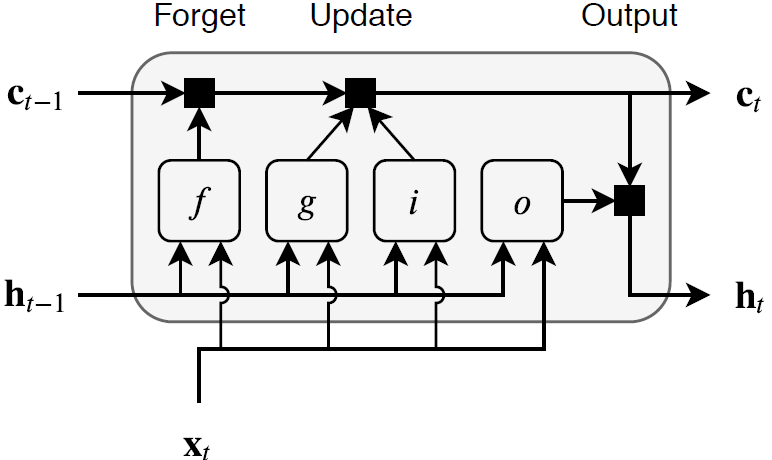

The state of the layer consists of the *hidden state* (**h**) (also known as the *output state*) and the *cell state *(**c**). The hidden state at time step *t* contains the output of the LSTM layer for this time step. The cell state contains information learned from the previous time steps. At each time step, the layer adds information to or removes information from the cell state. The layer controls these updates using *gates*.The following components control the cell state and hidden state of the layer.


$$\matrix{
\text{Input gate } i & \text{Control level of cell state update}\cr
\text{Forget gate } f & \text{Control level of cell state reset (forget)}\cr
\text{Cell candidate } g & \text{Add information to cell state}\cr
\text{Output gate } o & \text{Control level of cell state added to hidden state}\cr
}$$


For more information about the computation, see the documentation. Another great source for understanding the way an LSTM works is [this page](https://colah.github.io/posts/2015-08-Understanding-LSTMs/).

## Application 1 -  Cryptocurrency investing strategies

We have hourly data for the open, high, low and close price as well as the volume for Bitcoin (BTC). We will use this data and try to make predictions for the future.

### Loading and visualizing the data

LSTM layers with the Bitcoins price fluctuations (check multiple options time scale input window etc.)

% load up and prepare the data
clear;close all;clc
d_BTC = flip(readtimetable('./Data/gemini_BTCUSD_1hr.csv'));% illustrate evolution

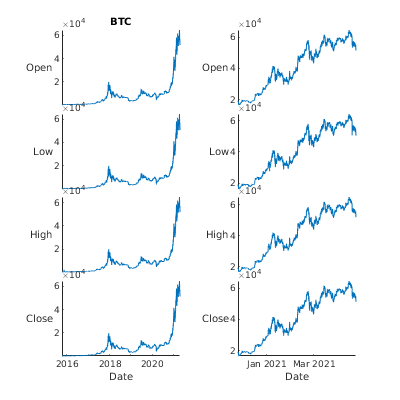

figure('Position',[0 0 400 400])
subplot(1,2,1)
stackedplot(d_BTC,{'Open', 'Low','High', 'Close'})
title('BTC');
subplot(1,2,2)
stackedplot(d_BTC(45000:end,:),{'Open', 'Low','High', 'Close'})

### Data selection and preparation

To start, we're going to focus on a subset of the data use only one of the four values (Close in our case).

indstart = 38000;%38000;%44150+5;%45873;
indend = 48560;%48032+5;
data = d_BTC(indstart:indend, "Close");
fprintf('start date: %s\nend date: %s\n',datestr(d_BTC.Date(indstart),'yyyy-mm-dd HH:MM'),...
                                       datestr(d_BTC.Date(indend),'yyyy-mm-dd HH:MM'));

start date: 2020-02-07 23:00
end date: 2021-04-22 23:00


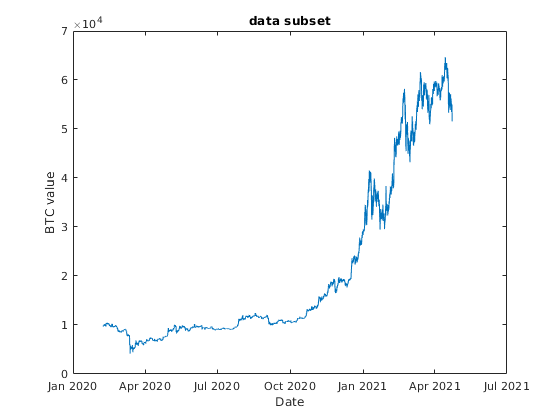

figure
plot(d_BTC.Date(indstart:indend), d_BTC.Close(indstart:indend));
xlabel('Date');ylabel("BTC value"); title("data subset");

In in illustration you can clearly observe an upward trend in the data. If we want to make predictions on this series, the presence of this upward trend might be a problem as the validation data might contain values that are a lot high than anything the model has seen before. Therefore, we will detrend the data. Additionally, we will use standardization to further limit the input range (Note: other options might work as well).

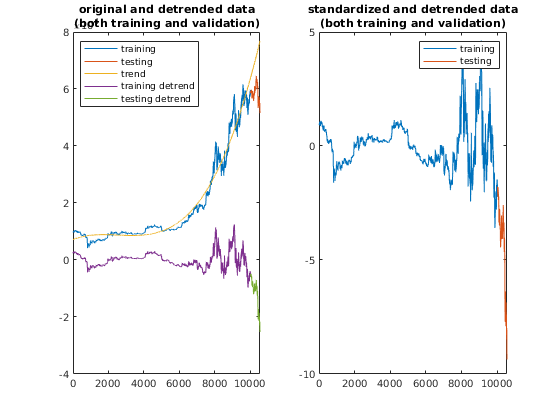

% training/validation ratio
vrat = 0.95; limidx = floor(height(data)*vrat);
traindata = data.Close(1:limidx-1);
testdata  = data.Close(limidx:end);

% detrend the data
detrendpolydegree = 3;
[ff,S,M] = polyfit(1:length(traindata),traindata,detrendpolydegree);

x = (1:height(data))';
traindata_prep = traindata - polyval(ff,x(1:limidx-1),[],M);
testdata_prep = testdata - polyval(ff,x(limidx:end),[],M); 

% illustrate
figure
subplot(1,2,1)
plot(1:limidx-1, traindata,'DisplayName','training');
hold on
plot(limidx:height(data), testdata,'DisplayName','testing');
plot(x, polyval(ff,x,[],M),'DisplayName','trend')
plot(x(1:limidx-1), traindata_prep,'DisplayName','training detrend')
plot(x(limidx:end), testdata_prep,'DisplayName','testing detrend')
title(["original and detrended data","(both training and validation)"])
legend('Location','northwest')

% standardize the data
mu = mean(traindata_prep); s = std(traindata_prep);
traindata_prep = (traindata_prep - mu) / s;
testdata_prep = (testdata_prep - mu) / s;
% illustrate
subplot(1,2,2)
plot(x(1:limidx-1), traindata_prep,'DisplayName','training');
hold on;
plot(x(limidx:end), testdata_prep,'DisplayName','testing');
title(["standardized and detrended data","(both training and validation)"])
legend()

### Using the model

Consider the following setup:

- we start with a fixed amount of capital

- we define a resolution to look at our data (we have used a one hour resolution up to now, but you could subsample the data for a more granular view)

- we define a training window (e.g. 2 months as we did before)

- we define a look ahead time for our model (e.g. one or two days)

- we automate the investment behavior a follows: if the value stays within a defined range, we hold on to our assets. If the value goes outside of the range, we either buy or sell (if capital is available).

- we suppose the investment is a high risk way, i.e. we will use all our capital to buy and sell all our assets if out model indicates us to do so.

We will try to find the settings that maximize our profit!

%% INVESTER SETTINGS
% trading costs  (ration of transaction amount)
csell = 0.015;
cbuy = 0.045;
% lead time (Hr)
lead_time = 24;
% starting wallet for both techniques
startcash = 0;
startcoin = 10;

#### The omniscient investor

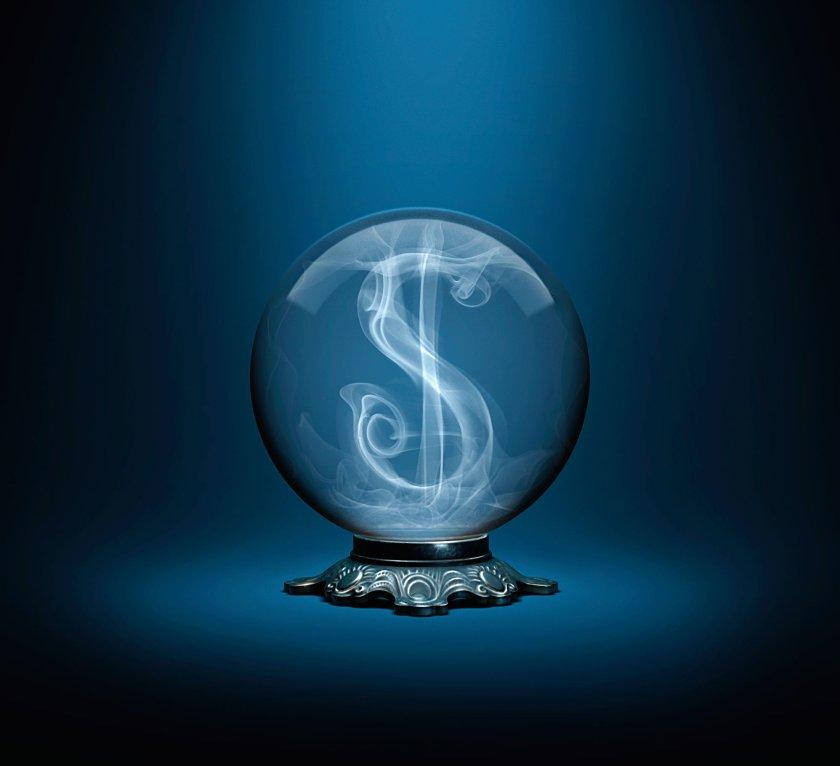

w_perf = Wallet(startcash,startcoin);
% select only subset of data as this will be really used for the perfect
% information simulation of the portfolio growth
idx = 1:lead_time:length(testdata);
d = testdata(idx);
d_sell = d * (1-csell);
d_buy = d * (1-cbuy);

% rules:
% crypto in wallet & ratio (X+1)/X < (1 - csell) => sell
% no crypto & ratio ratio (X+1)/X > (1 + cbuy) => buy
V = zeros(length(d)-1,0);
for i = 1:length(d)-1
    if d(i+1) / d(i) < (1-csell)
        w_perf = sell(w_perf,d(i));
    elseif d(i+1) / d(i) > (1+cbuy)
        w_perf = buy(w_perf,d(i));
    end
    fprintf('%i: %1.2f cash, %1.2f BTC\n',i, w_perf.cash, w_perf.crypto)
    V(i) = value(w_perf,d(i));
end

1: 0.00 cash, 10.00 BTC
2: 0.00 cash, 10.00 BTC
3: 588550.20 cash, 0.00 BTC
4: 588550.20 cash, 0.00 BTC
5: 588550.20 cash, 0.00 BTC
6: 588550.20 cash, 0.00 BTC
7: 588550.20 cash, 0.00 BTC
8: 588550.20 cash, 0.00 BTC
9: 588550.20 cash, 0.00 BTC
10: 588550.20 cash, 0.00 BTC
11: 588550.20 cash, 0.00 BTC
12: 588550.20 cash, 0.00 BTC
13: 0.00 cash, 9.80 BTC
14: 0.00 cash, 9.80 BTC
15: 0.00 cash, 9.80 BTC
16: 620795.70 cash, 0.00 BTC
17: 620795.70 cash, 0.00 BTC
18: 620795.70 cash, 0.00 BTC
19: 620795.70 cash, 0.00 BTC
20: 620795.70 cash, 0.00 BTC
21: 620795.70 cash, 0.00 BTC
22: 620795.70 cash, 0.00 BTC


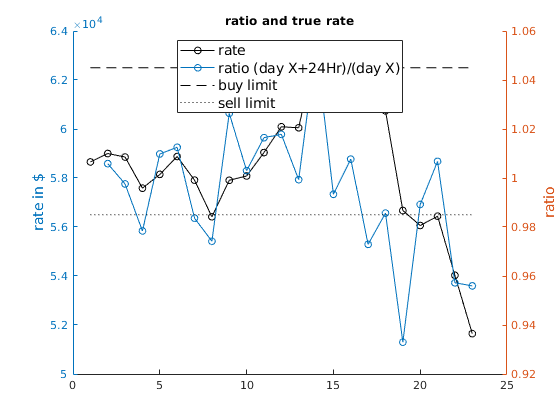

% illustrations
figure 
hold on
yyaxis left
plot(d,'-ok','displayname','rate')
ylabel('rate in $','fontsize', 12);
yyaxis right
ylabel('ratio','fontsize', 12)
plot(2:length(d),d(2:end)./d(1:end-1),'-o','color',[0 0.4470 0.7410],'displayname',sprintf('ratio (day X+%iHr)/(day X)',lead_time)); 
hold on;
plot((1+cbuy).*ones(size(d)),'--k','displayname','buy limit')
plot((1-csell).*ones(size(d)),':k','displayname','sell limit')
legend('fontsize', 12,'location','north');
title('ratio and true rate')

#### The RNN investor

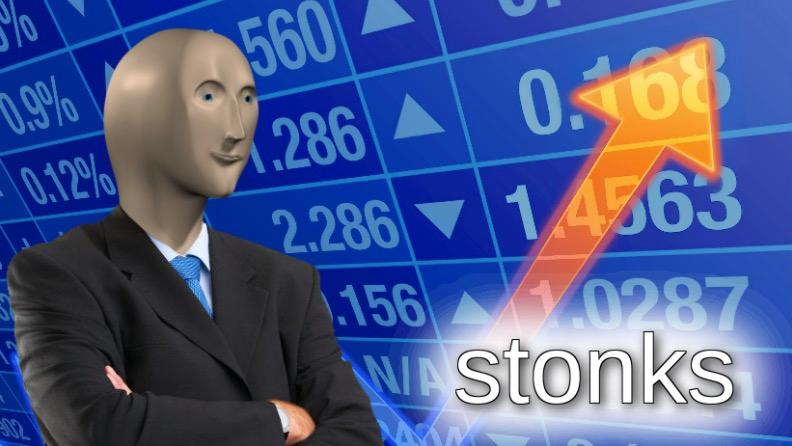

%% RNN INVESTOR
% 1. transform data in input and output vectors
xtrain = traindata_prep(1:end-1)';
ytrain = traindata_prep(2:end)';
xtest = [traindata_prep(end); testdata_prep(1:end-1)]';
ytest = testdata_prep(1:end)';

% 2. Model building stage
% build the network (1D input, 1D output, regression type)
layers = [sequenceInputLayer(1)...
          lstmLayer(100)...
          dropoutLayer(0.1)...
          batchNormalizationLayer()...
          fullyConnectedLayer(1)...
          regressionLayer];
% set the training options
options = trainingOptions('adam', ...
                          'GradientThreshold',1,...
                          'MaxEpochs',1000, ...
                          'LearnRateSchedule','piecewise', ...
                          'LearnRateDropPeriod',750, ...
                          'LearnRateDropFactor',0.9,...
                          'Verbose',0, ...
                          'Plots','none',...
                          'ExecutionEnvironment', 'gpu'...
                      );

%% 3. Model training stage
% actual training (takes a while)
try
    %error('train instead of load');
    load('trained_net', 'net')
catch
    [net, info] = trainNetwork(xtrain,ytrain,layers,options);
    save('trained_net','net')
end

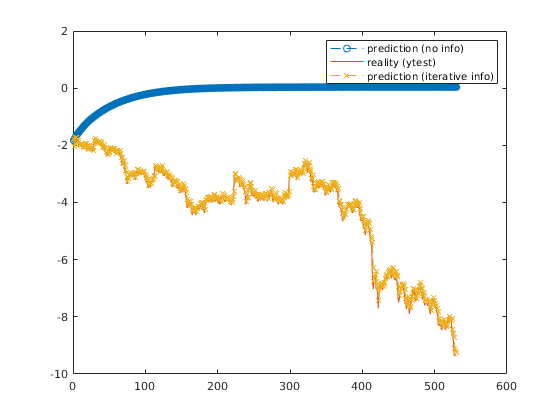

%% quicktest: model performance with actual updates:
resetState(net);
perfnet = predictAndUpdateState(net, xtrain);
% prediction using own value as reinforcement
yperf = zeros(size(ytest));

for i = 1:length(xtest)
    if i <= 1
        [perfnet, yperf(:,i)] = predictAndUpdateState(perfnet, xtest(:,i));
    else
        [perfnet, yperf(:,i)] = predictAndUpdateState(perfnet, yperf(:,i-1));
    end
end
yultimate = zeros(size(ytest));
for i = 1:length(xtest)
    [perfnet, yultimate(:,i)] = predictAndUpdateState(perfnet, xtest(:,i));
end
figure
plot(yperf,'--o','displayname','prediction (no info)'); hold on
plot(ytest,'-','displayname','reality (ytest)');
plot(yultimate,'--x','displayname','prediction (iterative info)')
legend()

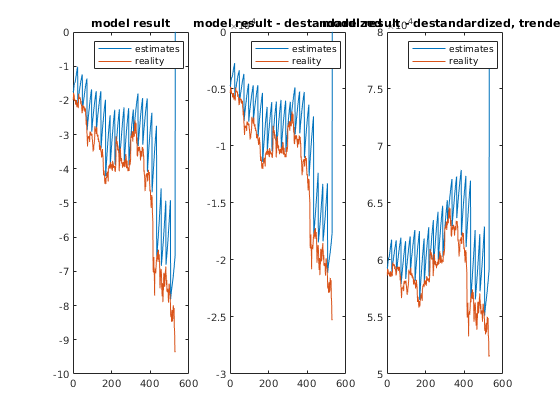

%% 4. Use model for predictions
% starting point: initialize the network state, predict on the training data.
resetState(net);
res = zeros(size(ytest));
for i = 1:lead_time:floor(length(ytest)/lead_time)*lead_time
    [net,res(:,i:i+lead_time-1)] = predictme(net,xtest(:,i:i+lead_time-1),lead_time);
end
figure
subplot(1,3,1)
plot(res,'displayname','estimates')
hold on
plot(ytest,'displayname','reality')
legend()
title('model result')
subplot(1,3,2)
plot(res*s+mu,'displayname','estimates')
hold on
plot(ytest*s+mu,'displayname','reality')
legend()
title('model result - destandardized')
subplot(1,3,3)
plot(polyval(ff,length(xtrain)+1:length(xtrain)+length(xtest),[],M) + res*s+mu,'displayname','estimates')
hold on 
plot(polyval(ff,length(xtrain)+1:length(xtrain)+length(xtest),[],M) + ytest*s+mu,'displayname','reality')
legend()
title('model result - destandardized, trended')

%% 5. Use predictions for investment strategy
w_ann = Wallet(startcash,startcoin);
% rules:
% crypto in wallet & ratio (X+1)/X < (1 - csell) => sell
% no crypto & ratio ratio (X+1)/X > (1 + cbuy) => buy
VV = zeros(length(d)-1,0);
res_invmap = polyval(ff,length(xtrain)+1:length(xtrain)+length(xtest),[],M) + res*s+mu;
for i = 1:length(d)-1
    ind = (i-1)*lead_time+lead_time;
    %res_invmap(ind) / d(i)
    if res_invmap(ind) / d(i) < (1-csell)
        w_ann = sell(w_ann,d(i));
        
    elseif res_invmap(ind) / d(i) > (1+cbuy)
        w_ann = buy(w_ann,d(i));
    end
    fprintf('%i: %1.2f cash, %1.2f BTC\n',i, w_ann.cash, w_ann.crypto)
    VV(i) = value(w_ann,d(i));
end

1: 0.00 cash, 10.00 BTC
2: 0.00 cash, 10.00 BTC
3: 0.00 cash, 10.00 BTC
4: 0.00 cash, 10.00 BTC
5: 0.00 cash, 10.00 BTC
6: 0.00 cash, 10.00 BTC
7: 0.00 cash, 10.00 BTC
8: 0.00 cash, 10.00 BTC
9: 0.00 cash, 10.00 BTC
10: 0.00 cash, 10.00 BTC
11: 0.00 cash, 10.00 BTC
12: 0.00 cash, 10.00 BTC
13: 0.00 cash, 10.00 BTC
14: 0.00 cash, 10.00 BTC
15: 0.00 cash, 10.00 BTC
16: 0.00 cash, 10.00 BTC
17: 0.00 cash, 10.00 BTC
18: 0.00 cash, 10.00 BTC
19: 0.00 cash, 10.00 BTC
20: 0.00 cash, 10.00 BTC
21: 0.00 cash, 10.00 BTC
22: 0.00 cash, 10.00 BTC


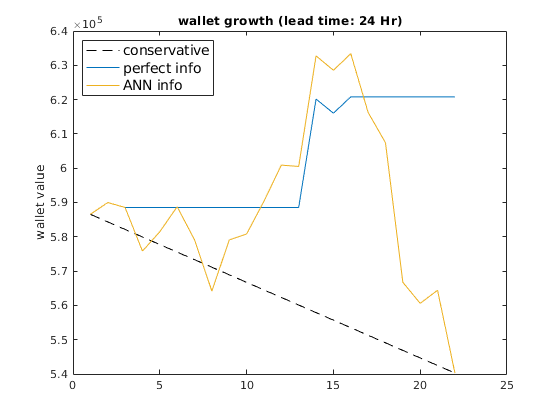

% portfolio growth
figure
plot([1 length(d)-1],[startcash+startcoin*d(1) startcash+d(end-1)/d(1)*V(1)],'--k','displayname','conservative')
hold on
plot(V,'displayname','perfect info','color',[0 0.4470 0.7410]);
plot(VV,'displayname','ANN info');
legend('location','northwest','fontsize', 12)
ylabel('wallet value')
title(sprintf("wallet growth (lead time: %i Hr)", lead_time));

function [net,res] = predictme(net, xv, lead_time)
    % initialize
    res = [];
    lnet = net;
    % first do the prediction to the lead time
    [lnet, res(:,1)] = predictAndUpdateState(lnet, xv(:,1));
    for i = 2:lead_time
         [lnet, res(:,i)] = predictAndUpdateState(lnet, res(:,i-1));
    end
    % followed by actual update of the net
    for i = 1:lead_time
        net = predictAndUpdateState(net, xv(:,i));
    end
end